cd('/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001')
ExperimentName='20220712_PM29_111_Achmut_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[17 18 19 20 21 22 23 24 25 26 27 28 29]

Dark_hours =     17    18    19    20    21    22    23    24    25    26    27    28    29


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

FilePostFix = '_20230412';

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

FilePostFix = '_20230412';

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

cd('/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 1; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),FilePostFix, '.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

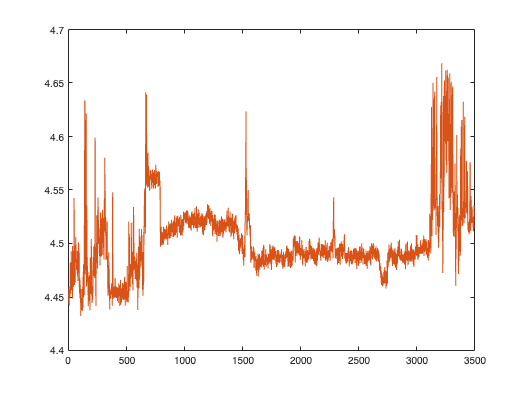

% sanity check for the new FLP analysis

i = 2;
filename=[analysis_name,num2str(i),FilePostFix, '.mat'];
tau_empTrunc_after = tau_empTrunc;

filename=[analysis_name,num2str(i),'h_20220830.mat'];
tau_empTrunc_before= tau_empTrunc;

figure
plot(tau_empTrunc_after)
hold on
plot(tau_empTrunc_before)


sum(tau_empTrunc_after - tau_empTrunc_before)

ans = 0

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220425_109_AChmut_SW_001FLIM001.mat'
     folder: '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001'
       date: '25-Apr-2022 16:46:11'
      bytes: 2994
      isdir: 0
    datenum: 7.3864e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(i),FilePostFix, '.mat'];;
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



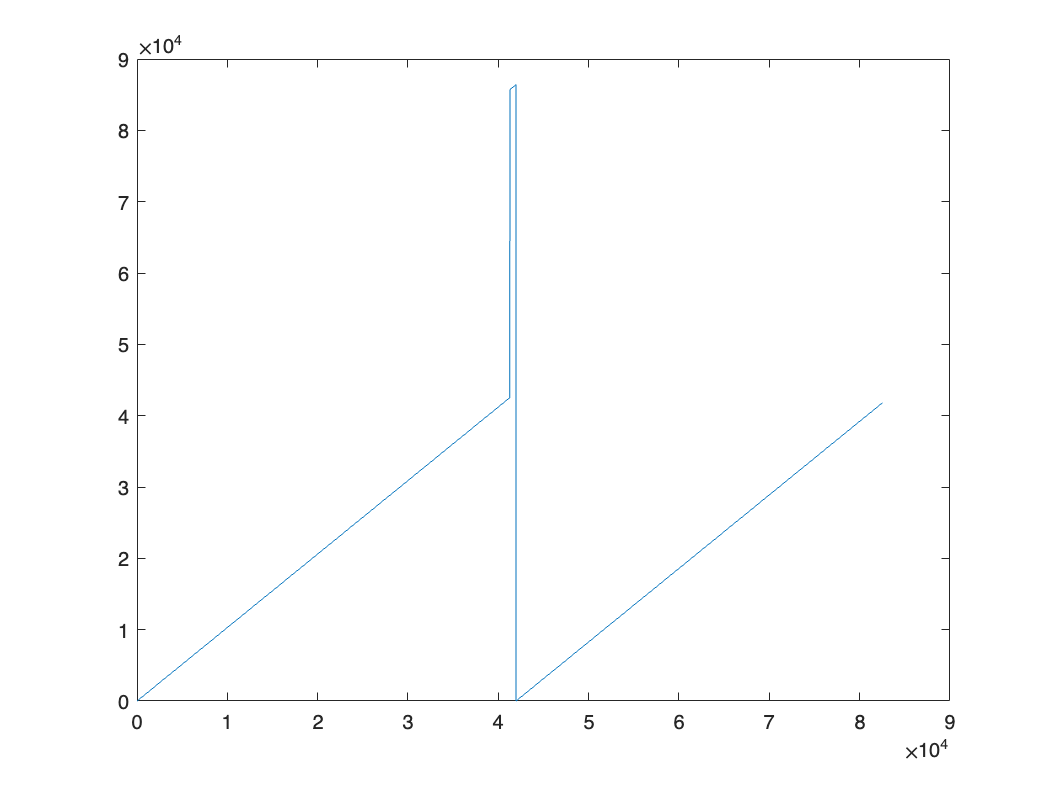

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)


% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename=[analysis_name,num2str(i),FilePostFix, '.mat'];;
    load(filename);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);

mkdir([analysis_name,'csv_', FilePostFix])

csv_name=[analysis_name,'csv_',FilePostFix,'/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save(['FLP_analysis_',FilePostFix,'.mat'])

cd('/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001')
ExperimentName='20220712_PM29_111_Achmut_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[17 18 19 20 21 22 23 24 25 26 27 28 29]

Dark_hours =     17    18    19    20    21    22    23    24    25    26    27    28    29


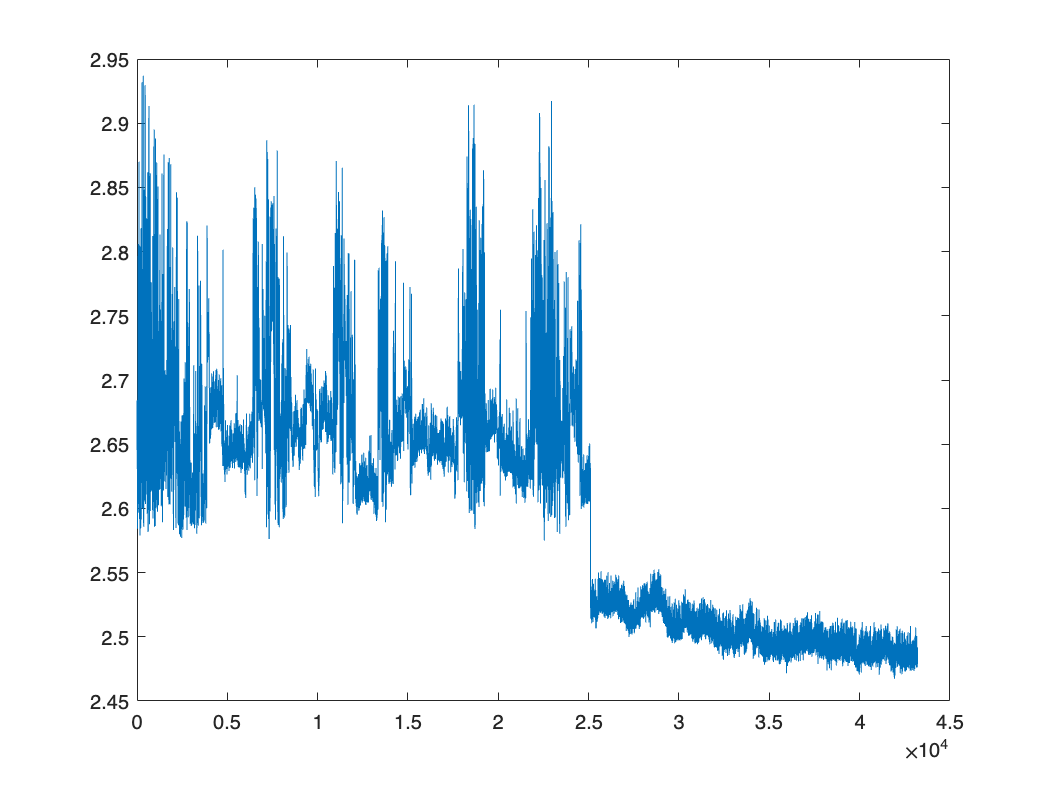

darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

FilePostFix = '_20230412';

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

load(['FLP_analysis_',FilePostFix,'.mat'])
tau_111 = tau_empTrunc_all_darkonly;
time_111 = time_z_all_darkonly;

figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


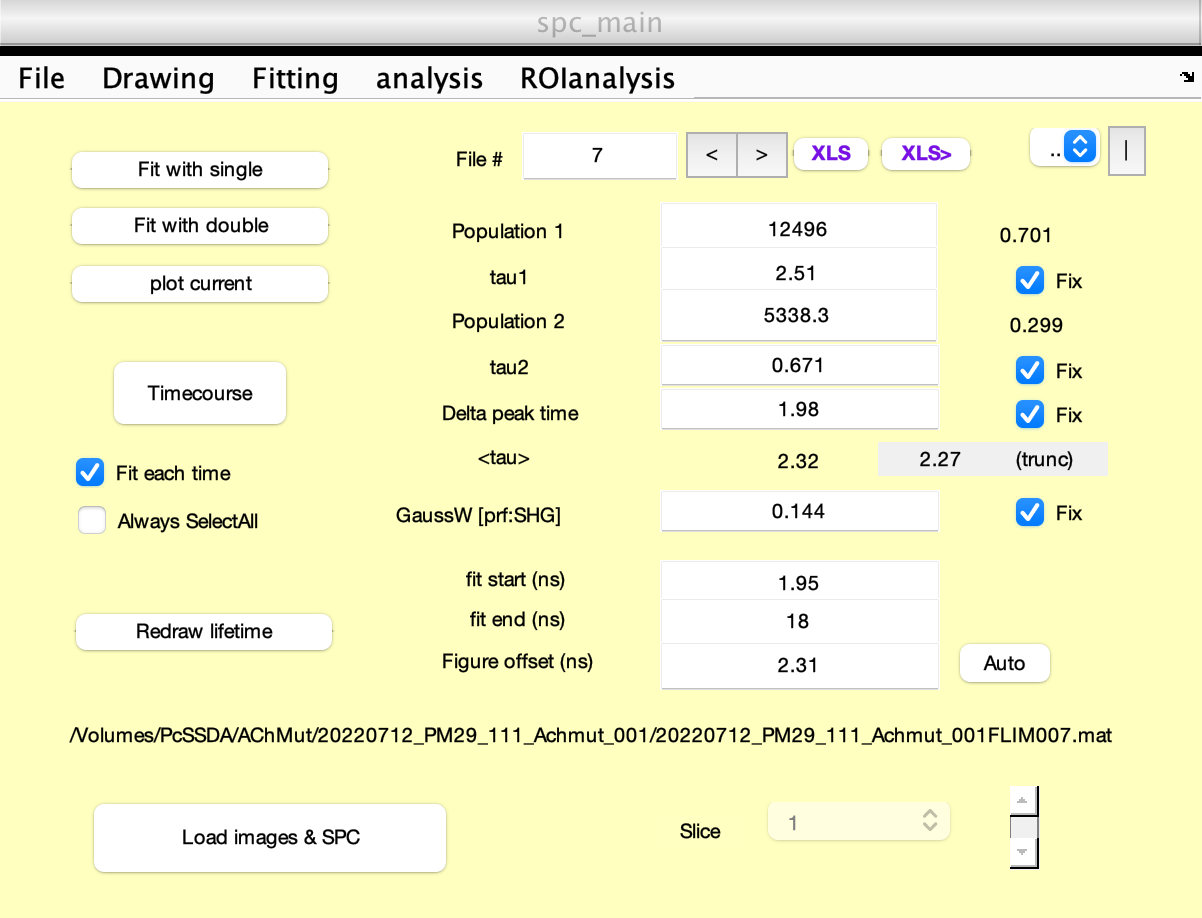

load(['FLP_analysis.mat'])

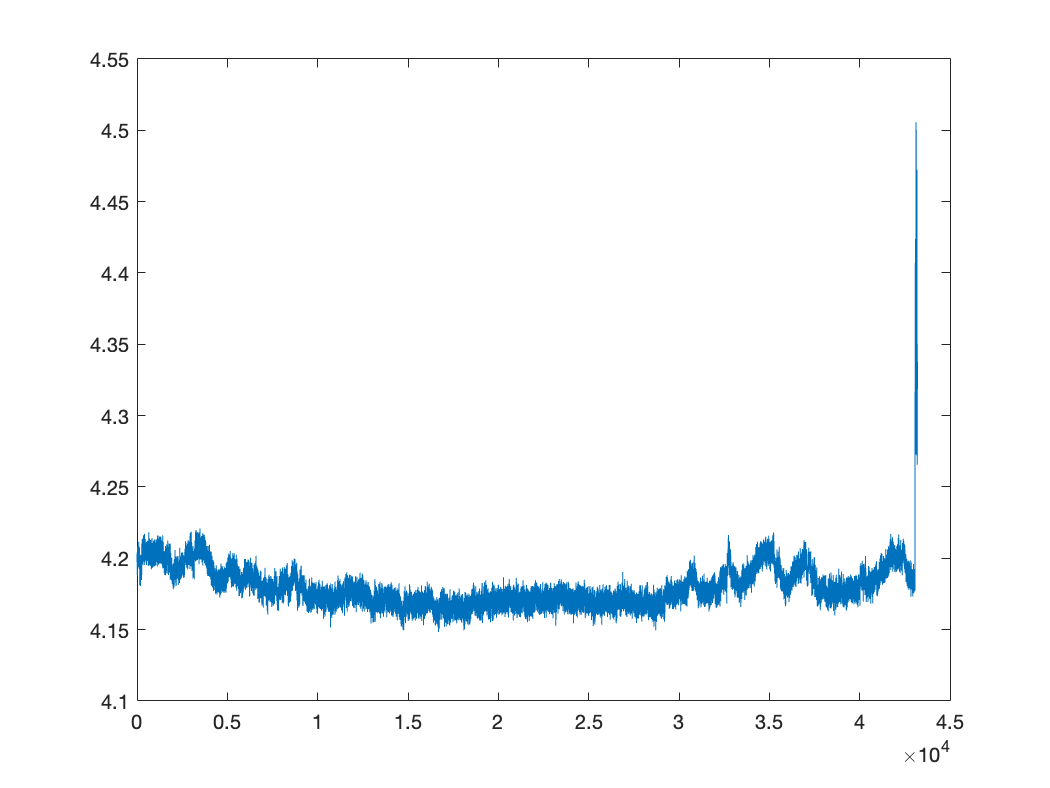

figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)

cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


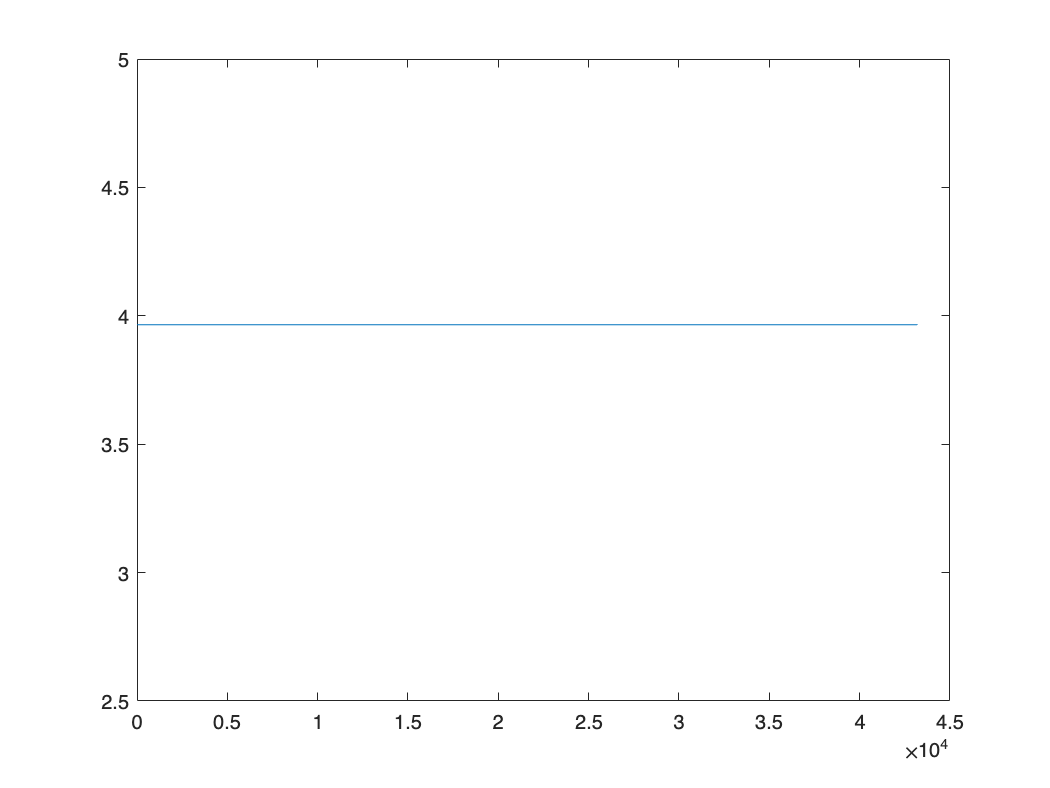

darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

FilePostFix = '_20230412';

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

load(['FLP_analysis_',FilePostFix,'.mat'])
tau_112 = tau_empTrunc_all_darkonly;
time_112 = time_z_all_darkonly;

figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)

cd('/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


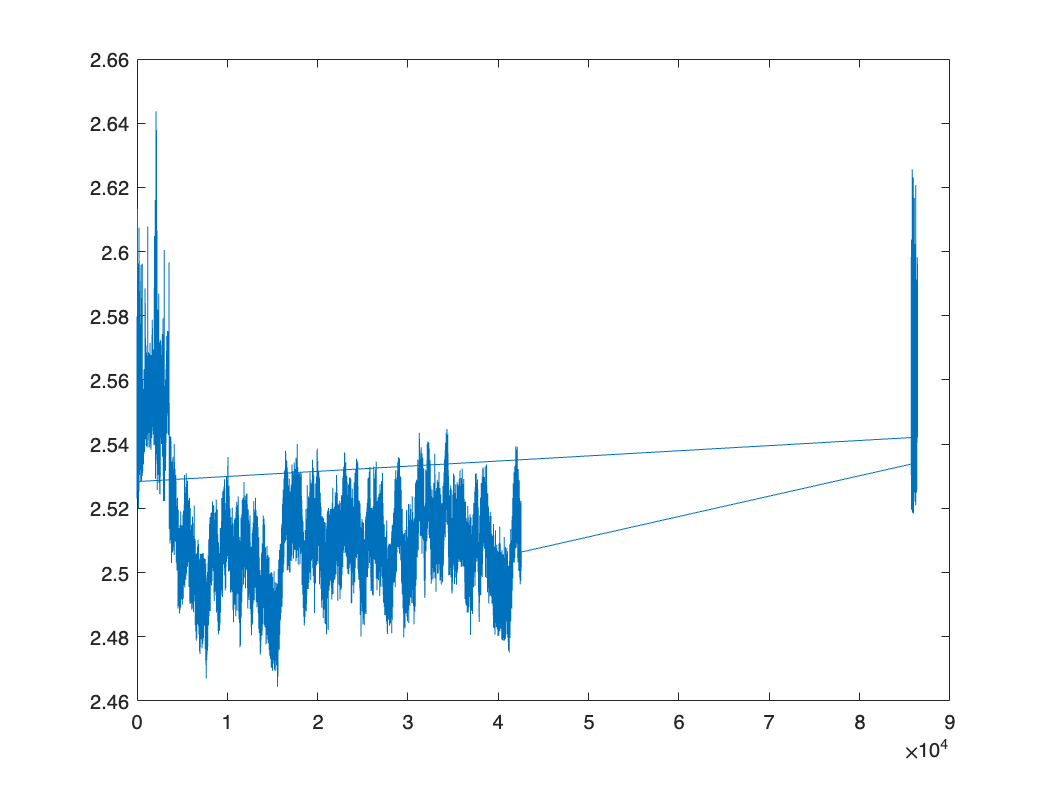

darktime_calc = 1; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

PeakGeneralization = 1; % 'PeakGeneralization'
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

load(['FLP_analysis_',FilePostFix,'.mat'])
tau_109 = tau_empTrunc_all_darkonly;
time_109 = time_z_all_darkonly;

figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)

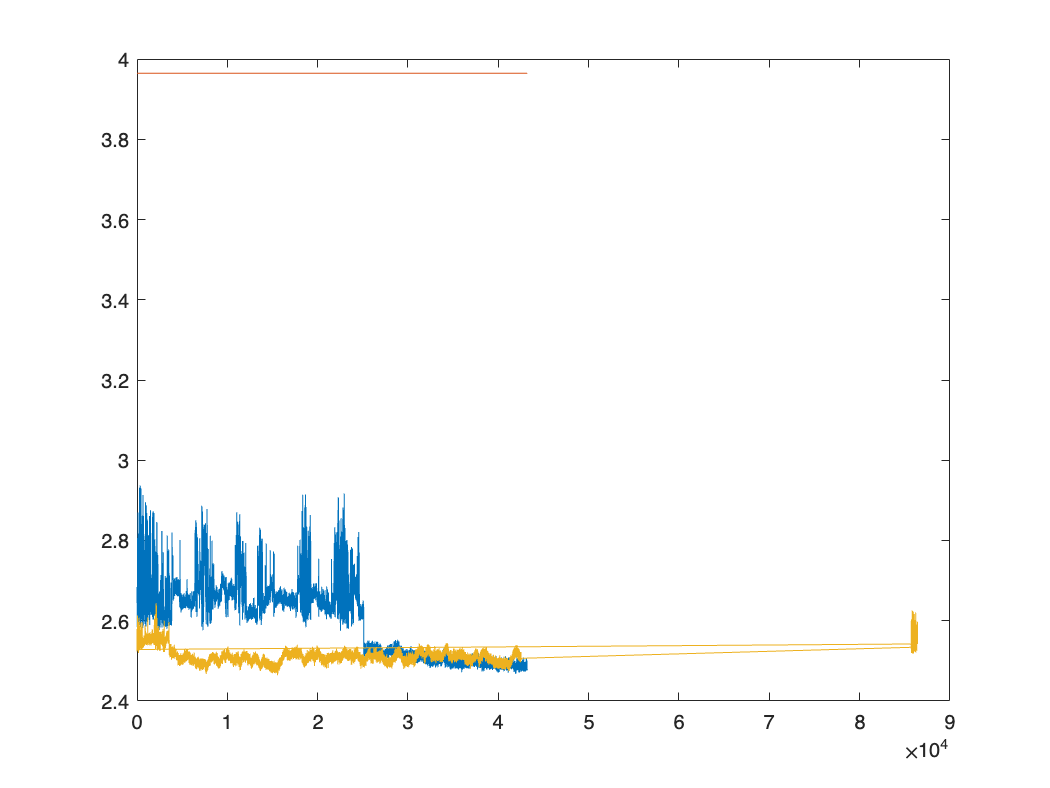

figure
plot(time_111, tau_111)
hold on
plot(time_112, tau_112)
hold on
plot(time_109, tau_109)

figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)